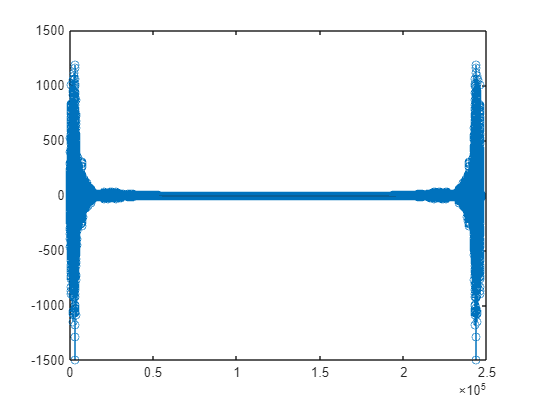

fs=48000;
% Load the speech signals
[y1,fs1] = audioread('pj_voice22.wav');
[y2,fs2] = audioread('l_v.wav');

% Ensure both signals have the same length
min_length = min(length(y1), length(y2));
y1 = y1(1:min_length);
y2 = y2(1:min_length);
N=length(y1);
%Normalize the signals to ensure they have the same amplitude range
y1 = y1 / max(abs(y1));
y2 = y2 / max(abs(y2));

% Apply FFT to the signals
Y1 = fft(y1,N);
Y2 = fft(y2,N);
stem(Y1);

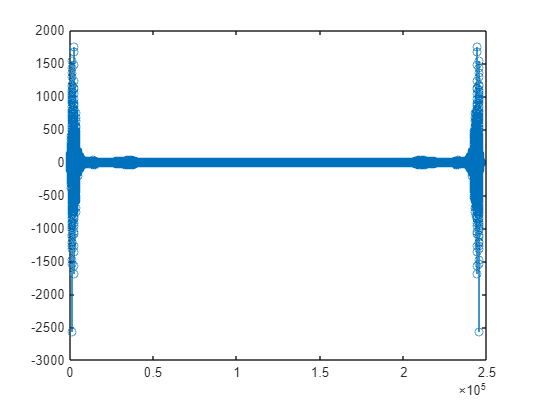

stem(Y2);

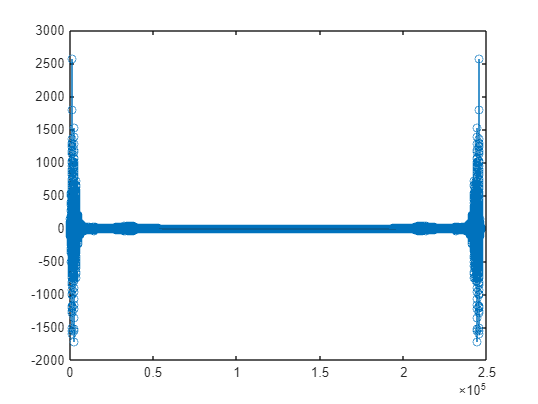


% Swap magnitudes and keep phases intact
Y1_mag = abs(Y1);
Y2_mag = abs(Y2);
Y1_phase = angle(Y1);
Y2_phase = angle(Y2);

Y1_swapped = Y2_mag .* exp(1i * Y1_phase);
Y2_swapped = Y1_mag .* exp(1i * Y2_phase);
stem(Y1_swapped);

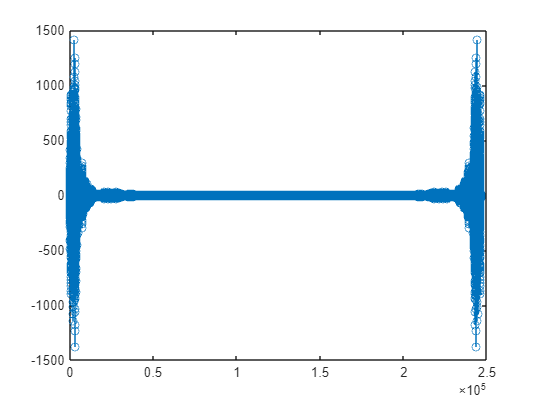

stem(Y2_swapped);

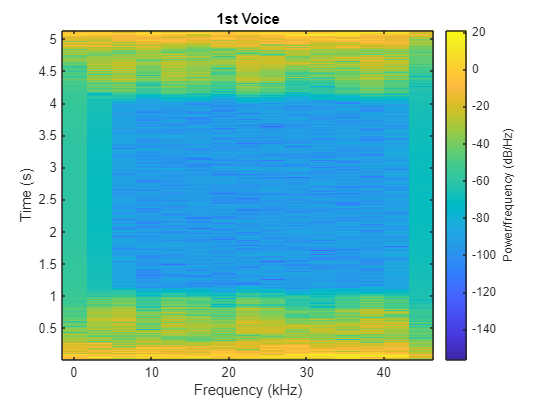


figure;
spectrogram(Y1, hann(20), 5, 15, fs, 'xaxis');
title('1st Voice');

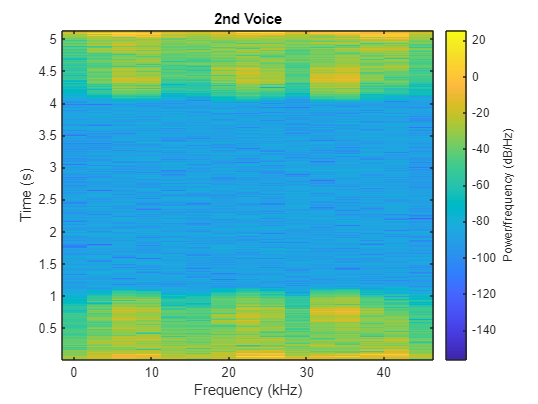

figure;
spectrogram(Y2, hann(20), 5, 15, fs, 'xaxis');
title('2nd Voice');


% Apply inverse FFT to get modified signals
y1_swapped = abs(ifft(Y1_swapped));
y2_swapped = abs(ifft(Y2_swapped));

% Listen to the modified signals
sound(y1_swapped, fs1);
pause(10);
sound(y2_swapped, fs2);